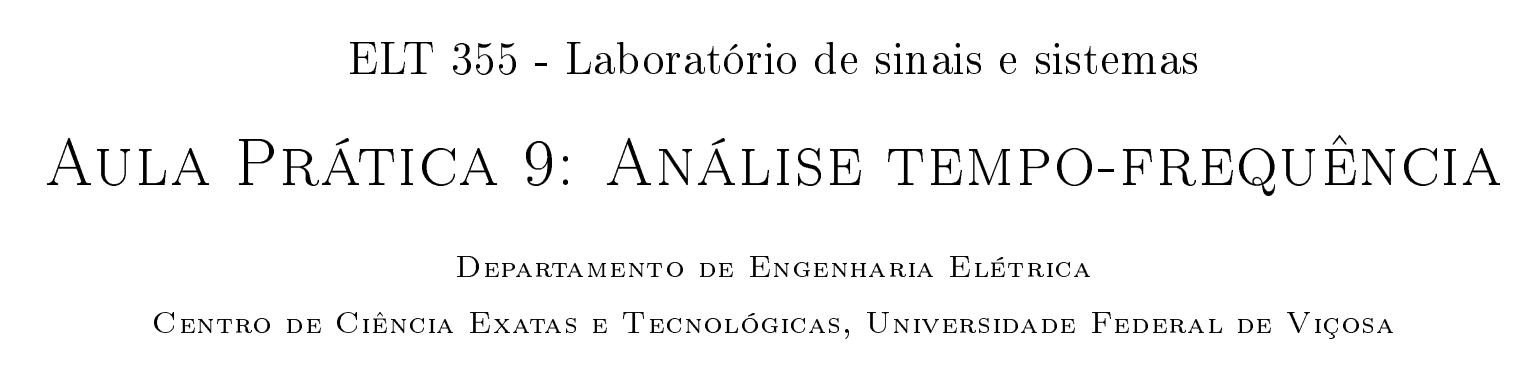

07/07/22

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

## Espectograma

**(Transformada de Fourier de Curta Duração)**

Espectograma -> como o conteúdo espectral de um sinal muda em função do tempo. Como a resposta em frequancia varia em função do tempo.

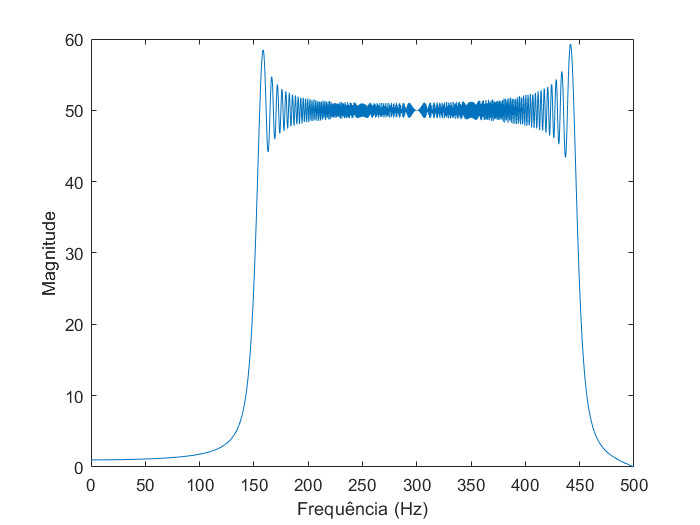

fs = 1000; % frequência de amostragem, para criar o passo de tempo
t = 0:1/fs:3; % vetor tempo

% parâmetros da função y
t1 = 3;
f1 = 450;
f0 = 150;
B = (f1-f0)/t1; 

y = cos(2*pi*(f0*t + (B/2)*(t.^2) )); % vetor da resposta de y(B,f0,t)
Y = abs(fft(y)); % função y no domínio da frequência

F = linspace(0, fs/2, round(length(y)/2));
plot(F,Y(1:round(length(y)/2)))
xlabel('Frequência (Hz)')
ylabel('Magnitude')

Através da imagem é possível perceber que o sinal possui um conteúdo espectral entre 150 à 450 Hz (existem magnitudes de sinais senoidais contrutores maiores que 0 nessa faixa de frequências).

Não é possível ver como a frequência aumenta ou abaixa no tempo.

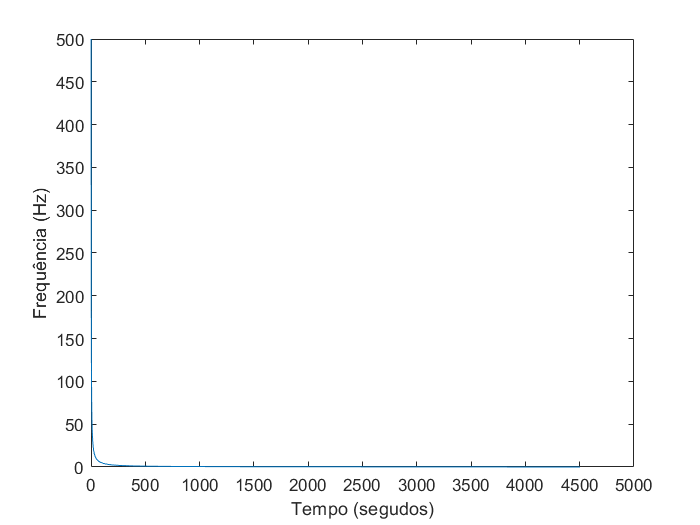

T = abs(fft(t));
plot(T(1:round(length(t)/2)),F);
xlabel('Tempo (segudos)')
ylabel('Frequência (Hz)')

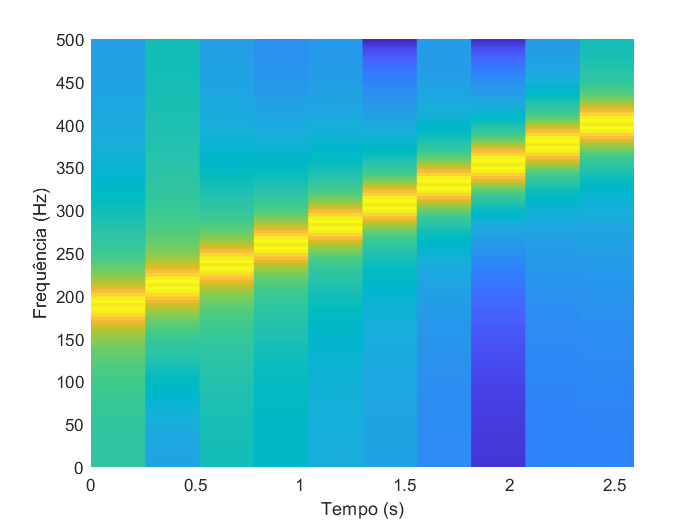

% entradas -> 
% sinal, n de pontos por janela, n pontos por overlap, n de
% pontos da transformada de Fourier, frequência de amostragem
[S,F,T] = espectrograma(y,256,20,256,fs);
% saida -> espectograma, frequência, tempo
figure
surf(T,F,10*log10(abs(S)), 'EdgeColor', 'none');
axis xy; axis tight; view(0,90);
xlabel('Tempo (s)')
ylabel('Frequência (Hz)')

Agora, atrávés do espectograma, é possível ver que a frequência aumenta no tempo de forma aproximadamente linear. Se tratando de som, seria um sinal sonoro de 2,5 segundos que vai ficando agudo de forma linear. Além disso, com o padrão de cores é possível também notar onde as amplitudes são mais expressivas, o que seria a intensidade do som em dada frequência. 

## Lena em áudio

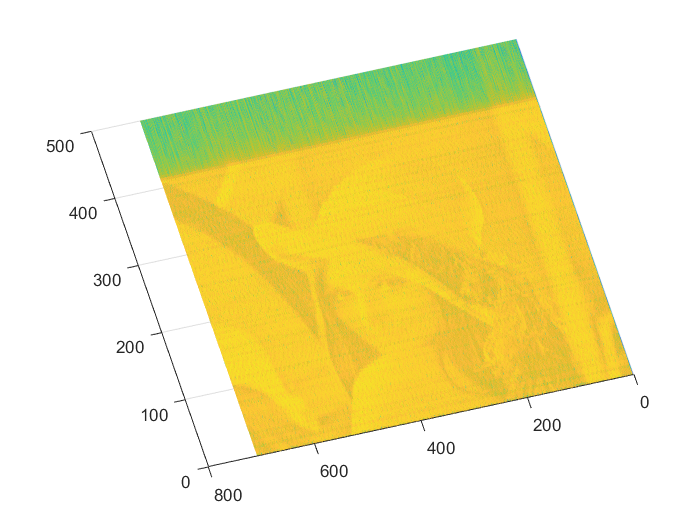

y = audioread('lena.wav');
[S,F,T] = espectrograma(y,256,20,256,fs);
figure
surf(T,F,10*log10(abs(S)), 'EdgeColor', 'none');

view([-164.6 -90.0])

# pesquisar o que é overlap

## Canto das Baleias

## Richard David James